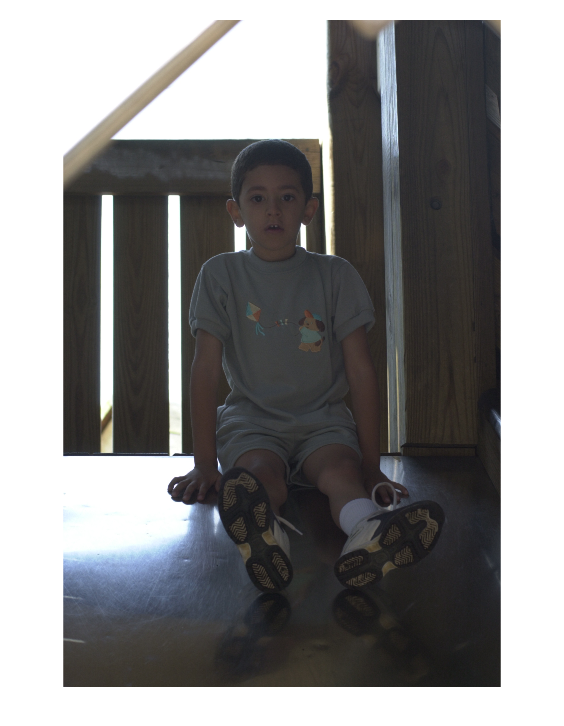

clear all;
I=imread("2.jpg");
%R
R=I(:,:,1);
[N1,M1]=size(R);
RD=double(R);
Rlog=log(RD+1);
Rfft2=fft2(RD);
H1 = ifftshift(Rfft2);
sigma=120; %尺度
%gaussian filter
F=zeros(N1,M1);  
for i=1:N1
    for j=1:M1
        F(i,j)=exp(-((i-N1/2)^2+(j-M1/2)^2)/(2*sigma*sigma));
    end
end
F=F./(sum(F(:)));
Ffft=fft2(ifftshift(F));
DR0=Rfft2.*Ffft;
DR=ifft2(DR0);
DRdouble=double(DR);
DRlog=log(DRdouble+1);
Rr=Rlog-DRlog;
%量化到0~255
me=mean(Rr,"all"); 
st=std2(Rr);
Dynamic=1.8;
Min = me - Dynamic*st;
Max = me + Dynamic*st;
for i=1:N1
    for j=1:M1
        Rr(i,j)= (Rr(i,j)-Min)/(Max-Min)*255;
        if (Rr(i,j)>255)
            Rr(i,j) = 255;
        elseif(Rr(i,j)<0)
            Rr(i,j) = 0;
        end
    end
end

%G
G=I(:,:,2);
[N1,M1]=size(G);
GD=double(G);
Glog=log(GD+1);
Gfft2=fft2(GD);
H2 = ifftshift(Gfft2);
%gaussian filter
F=zeros(N1,M1);
for i=1:N1
    for j=1:M1
        F(i,j)=exp(-((i-N1/2)^2+(j-M1/2)^2)/(2*sigma*sigma));
    end
end
F=F./(sum(F(:)));
Ffft=fft2(ifftshift(F));
DG0=Gfft2.*Ffft;
DG=ifft2(DG0);
DGdouble=double(DG);
DGlog=log(DGdouble+1);
Gg=Glog-DGlog;
%量化到0~255
me=mean(Gg,"all");
st=std2(Gg);
Min = me - Dynamic*st;
Max = me + Dynamic*st;
for i=1:N1
    for j=1:M1
        Gg(i,j)= (Gg(i,j)-Min)/(Max-Min)*255;
        if (Gg(i,j)>255)
            Gg(i,j) = 255;
        elseif(Gg(i,j)<0)
            Gg(i,j) = 0;
        end
    end
end

%B
B=I(:,:,3);
[N1,M1]=size(B);
BD=double(B);
Blog=log(BD+1);
Bfft2=fft2(BD);
H3 = ifftshift(Bfft2);
%gaussian filter
F=zeros(N1,M1);
for i=1:N1
    for j=1:M1
        F(i,j)=exp(-((i-N1/2)^2+(j-M1/2)^2)/(2*sigma*sigma));
    end
end
F=F./(sum(F(:)));
Ffft=fft2(ifftshift(F));
DB0=Bfft2.*Ffft;
DB=ifft2(DB0);
DBdouble=double(DB);
DBlog=log(DBdouble+1);
Bb=Blog-DBlog;
%量化到0~255
me=mean(Bb,"all");
st=std2(Bb);
Min = me - Dynamic*st;
Max = me + Dynamic*st;
for i=1:N1
    for j=1:M1
        Bb(i,j)= (Bb(i,j)-Min)/(Max-Min)*255;
        if (Bb(i,j)>255)
            Bb(i,j) = 255;
        elseif(Bb(i,j)<0)
             Bb(i,j) = 0;
        end
    end
end


I0(:,:,1)=Rr;
I0(:,:,2)=Gg;
I0(:,:,3)=Bb;

I1(:,:,1)=DR;
I1(:,:,2)=DG;
I1(:,:,3)=DB;

figure
imshow(I); %原圖

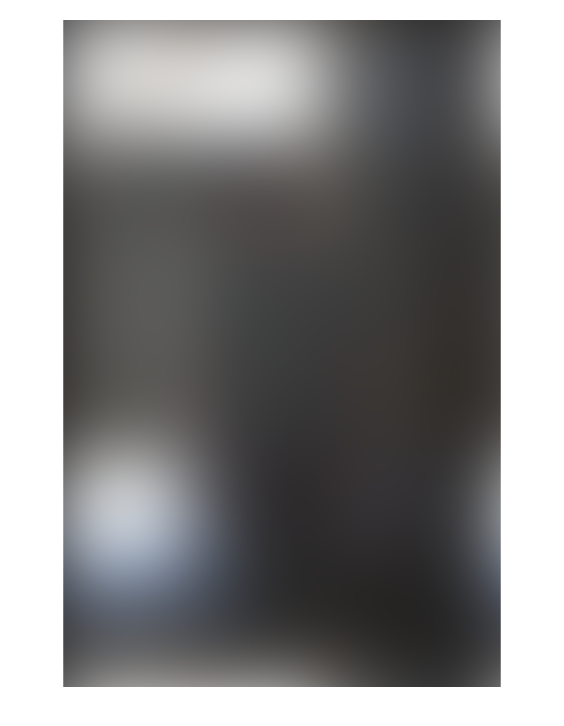

imshow(uint8(I1)); %與濾波器卷積後

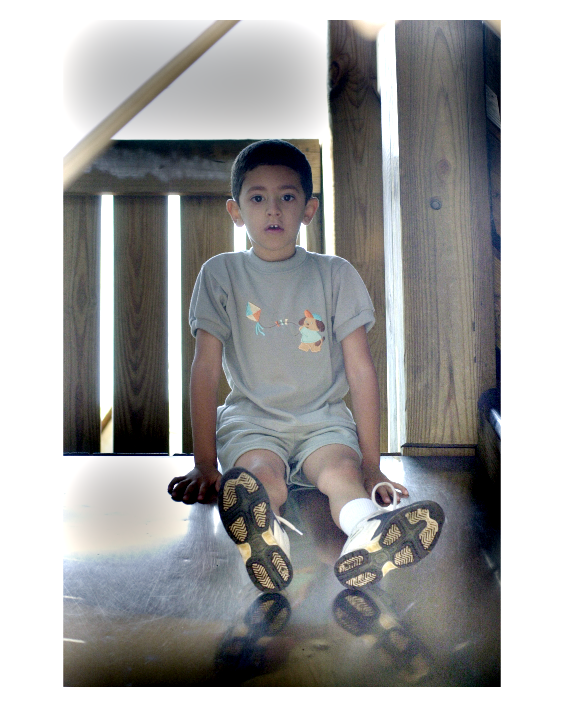

imshow(uint8(I0)); %最終圖像

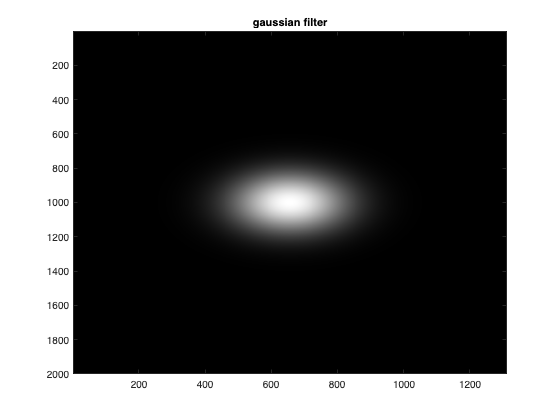

figure;
imagesc((abs((F))));
title('gaussian filter');
colormap('gray');

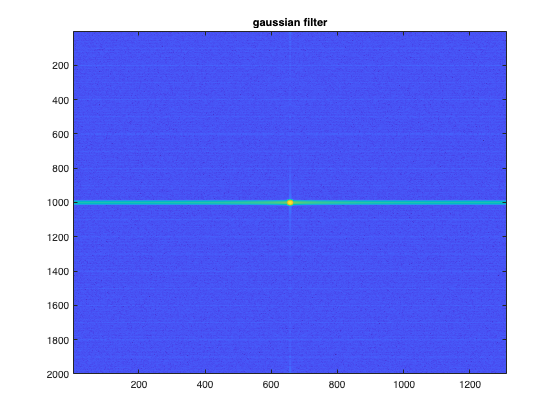

H = ifftshift(Ffft);
figure
imagesc(log10(abs(H)));
title('gaussian filter');
colormap('parula');

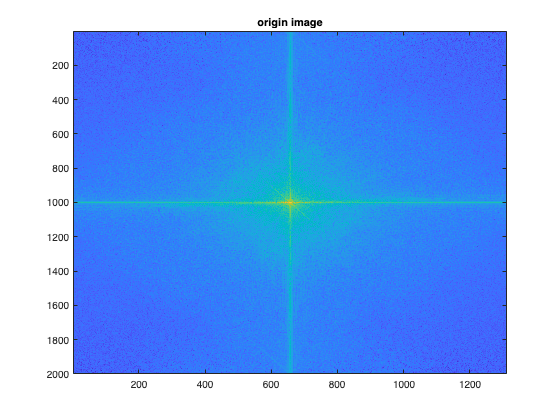

figure;
imagesc(log10(abs(H1)+abs(H2)+abs(H3)));
title('origin image');
colormap('parula');

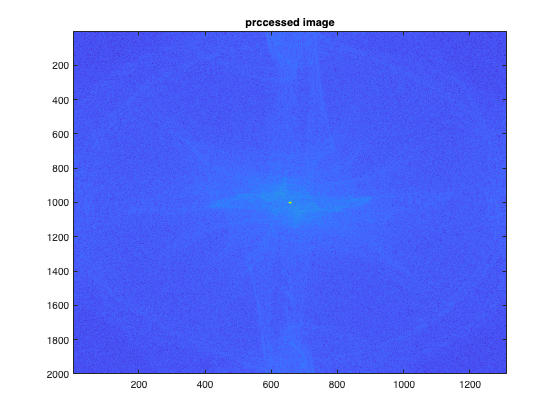

rfft=fft2(uint8(DR));
Hf1 = ifftshift(rfft);
gfft=fft2(uint8(DG));
Hf2 = ifftshift(gfft);
bfft=fft2(uint8(DB));
Hf3 = ifftshift(bfft);
figure;
imagesc(log10(abs(Hf1)+abs(Hf2)+abs(Hf3)));
title('prccessed image');
colormap('parula');